## Set 3: Motion Planning & Trajectory Generation (75 points) 

For this set, you may do any mode without requirment of doing the others.

Normal Mode: (10 Points) 

Given a set of via points in configuration space (3D) , compute the following

- Determine suitable verlocity and acceleration

- Coefficients of quintic polynomial

- Plot each joint configuration vs. time

- Plot joint's velocity of each joint vs. time

- Plot joint's acceleration of each joint vs. time

via_point = [0 pi/4 pi/2 0;0 -pi/6 -pi/4 0;0 pi/6 pi/3 0];
duration = [1;1.5;2];
vavg = zeros(3,3);
q_dot = zeros(3,4);

t_viapoint = [0];
for i = 1:3
    t_viapoint = cat(2, t_viapoint, t_viapoint(i)+duration(i));
end

for i = 1:size(vavg, 2)
    vavg(:,i) = (via_point(:,i+1) - via_point(:,i))/duration(i);
end
for i = 1:(size(vavg, 2)-1)
    for j = 1:3
        if sign(vavg(j,i)*vavg(j,i+1)) == 1
            q_dot(j,i+1) = (vavg(j,i) + vavg(j,i+1))/2;
        else
            q_dot(j, i+1) = 0;
        end
    end
end

aavg = zeros(3,3);
q_ddot = zeros(3,4);

for i = 1:size(aavg, 2)
    aavg(:,i) = (q_dot(:,i+1) - q_dot(:,i))/duration(i);
end
for i = 1:(size(aavg, 2)-1)
    for j = 1:3
        if sign(aavg(j,i)*aavg(j,i+1)) == 1
            q_ddot(j,i+1) = (aavg(j,i) + aavg(j,i+1))/2;
        else
            q_ddot(j, i+1) = 0;
        end
    end
end
vavg

vavg =     0.7854    0.5236   -0.7854
   -0.5236   -0.1745    0.3927
    0.5236    0.3491   -0.5236


q_dot

q_dot =          0    0.6545         0         0
         0   -0.3491         0         0
         0    0.4363         0         0


aavg

aavg =     0.6545   -0.4363         0
   -0.3491    0.2327         0
    0.4363   -0.2909         0


q_ddot

q_ddot =      0     0     0     0
     0     0     0     0
     0     0     0     0


%placeholder values
T = [];
Q = [];
V = [];
Ac = [];
C = [];
%iterate dims(xyz)
for i = 1:3
    %iterate sub-traj
    q = [];
    v = [];
    ac = [];
    t = [];
    c = [];
    for j = 1:3
    q0 = via_point(i,j);
    v0 = q_dot(i,j);
    ac0 = q_ddot(i,j);
    q1 = via_point(i,j+1);
    v1 = q_dot(i,j+1);
    ac1 = q_ddot(i, j+1);
    t0 = t_viapoint(j);
    tf = t_viapoint(j+1);
    

use the function quinticTrajectory

    [a, td, qd, vd, ad] = quinticTraj(q0,v0,ac0,q1,v1,ac1,t0,tf);

C = C(:,:,1) =

         0   -1.4593  118.5368
         0    6.6662 -186.3787
         0   -8.7266  115.9689
    5.2360    6.0117  -35.0975
   -7.1995   -1.9393    5.1542
    2.7489    0.2327   -0.2945


C(:,:,2) =

         0   -0.3814  -59.2684
         0    0.3232   93.1893
         0   -0.7757  -57.9845
   -3.8397    0.3620   17.5487
    5.4105   -0.0517   -2.5771
   -2.0944   -0.0000    0.1473


C(:,:,3) =

         0   -0.9729   79.0246
         0    4.4441 -124.2524
         0   -5.8178   77.3126
    3.4907    4.0078  -23.3983
   -4.7997   -1.2928    3.4361
    1.8326    0.1551   -0.1963


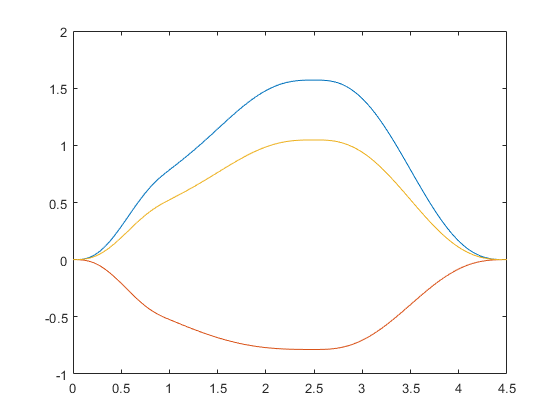

    t = horzcat(t, td);

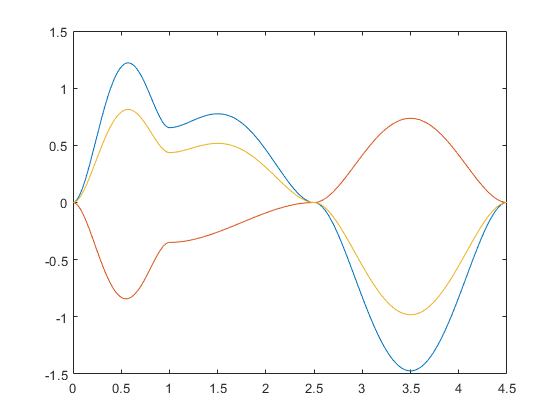

    q = horzcat(q, qd);

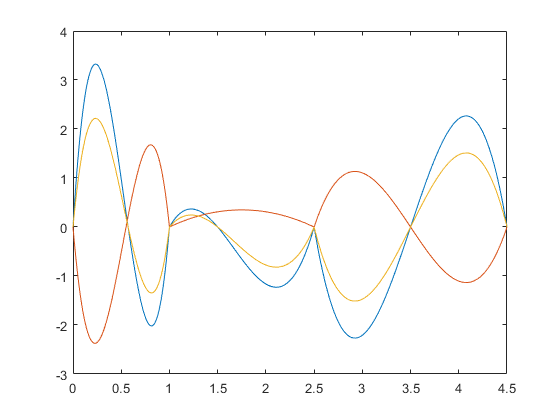

    v = horzcat(v, vd);

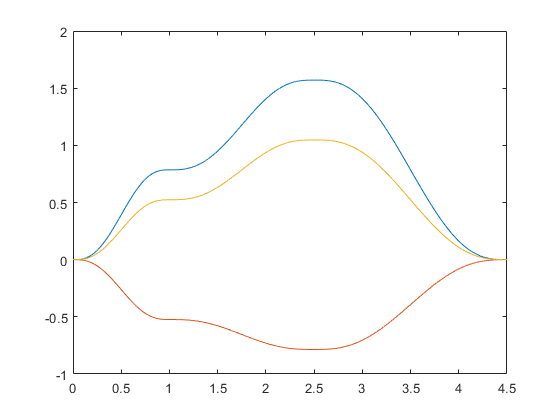

    ac = horzcat(ac, ad);
    c = horzcat(c,a);
    end
    T = t;
    Q = vertcat(Q,q);
    V = vertcat(V,v);
    Ac = vertcat(Ac,ac);
    C = cat(3,C,c);

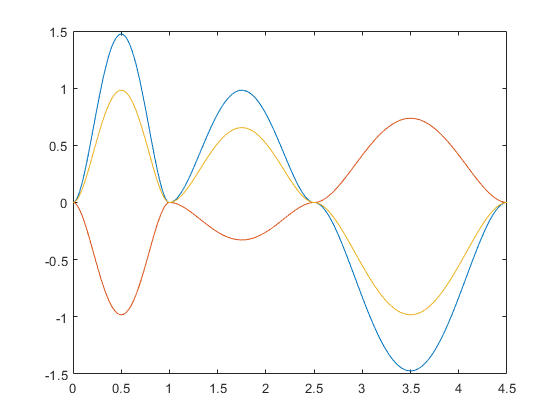

end

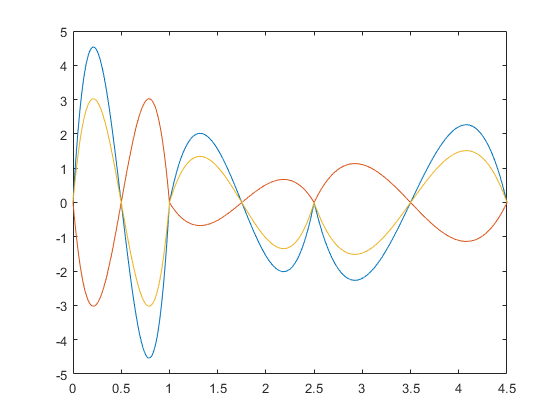

%we get c values

C
plot(T,Q)
plot(T,V)
plot(T,Ac)

Comparison with RST implimentation.

wpts = via_point;
tpts = t_viapoint;
tvec = 0:0.001:4.5;

[q, qd, qdd, pp] = quinticpolytraj(wpts, tpts, tvec);

plot(tvec, q)
plot(tvec, qd)
plot(tvec, qdd)

Hard Mode: (15 Points)

Assume that you are planning in 2D for the 2nd joint and the 3rd joint only. And the obstacle looks like this in cross-sectional view. (It's basically a step that revolves around the global z-axis)

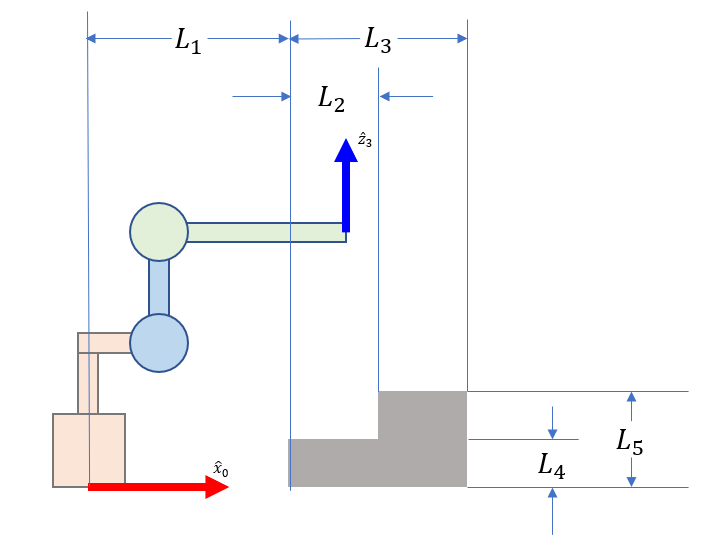

Figure 2: Cross-sectional view

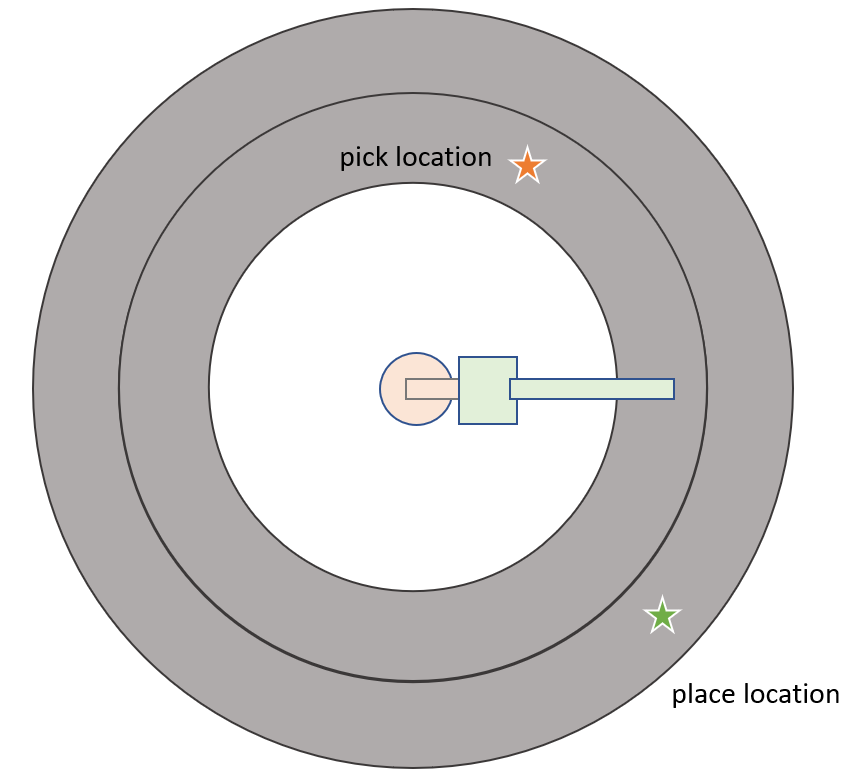

Figure 3: Top View with pick and place location

Explain (in detail) your motion planning algorithm to generate the a set of via points (in 3D) without collision between end-efffector and the obstacles. You don't have to implement the algorithm. But any unexplained steps will be penalized by 3 points. (If you have 2 unexplained steps, you will be penalized by 6 points. The maximum penalty is 15 points.) If you are not sure whether to explain, you may ask Aj. Pi. 

Chaos Mode: (25)

Implement time-optimal trajectory for 3-DOF given a set of via-points with the following constraints.

Explain your code in details.

Hard/Chaos Mode: (15/25 Points) 

Implement your planning algorithm in MATLAB.

Use built-in functionalities from MATLAB's Robotics System Toolbox (15 points)

Implement your own version of algorithm (25 points)